# **VAJE 6**

H6(z) = H2(z)*H1(z) = ((1-z^-k)^m)*((1-z^-n)/(1-z^-1))

(ojacanje) G = G1*G2 = (2^m)*n

(delay) D = D1+D2 = (k/2)*m + (n-1)/2

ce je m=1: poudarja spremembe ('prvi odvod')

ce m=2: poudarjamo vrhove ('drugi odvod')

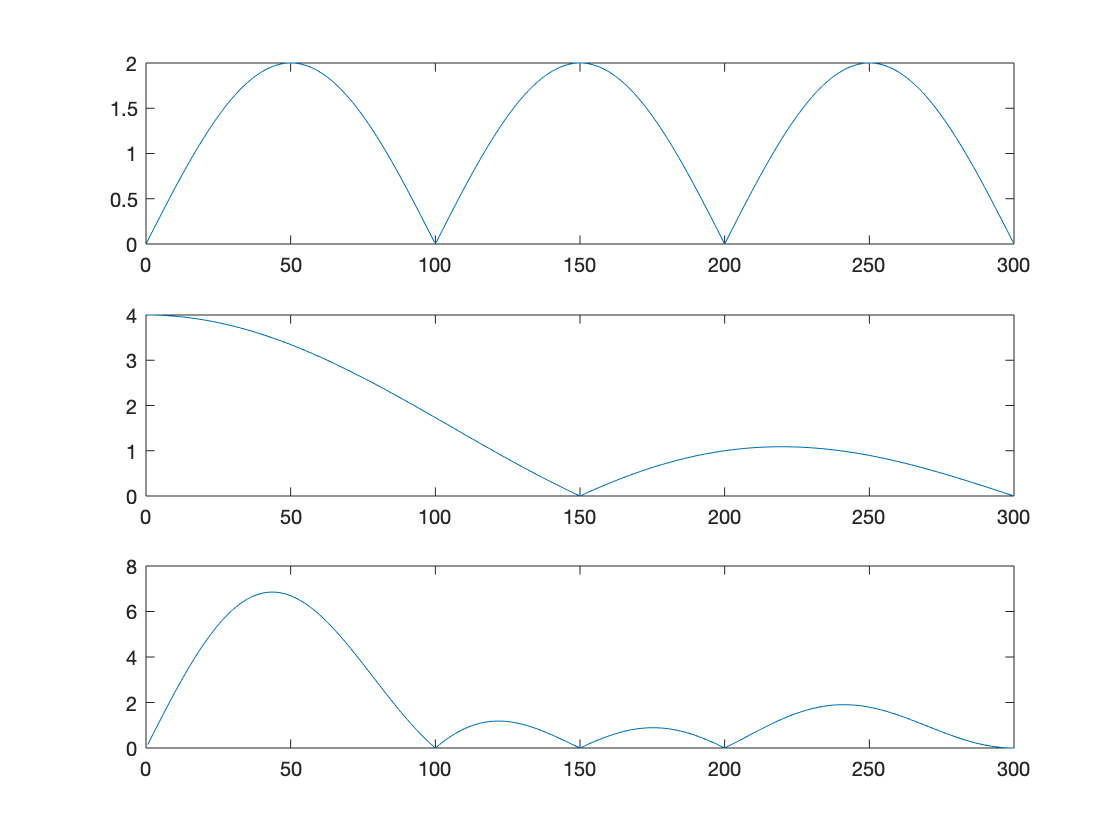

transferCharacteristic6 (600,6,1,4); figure;

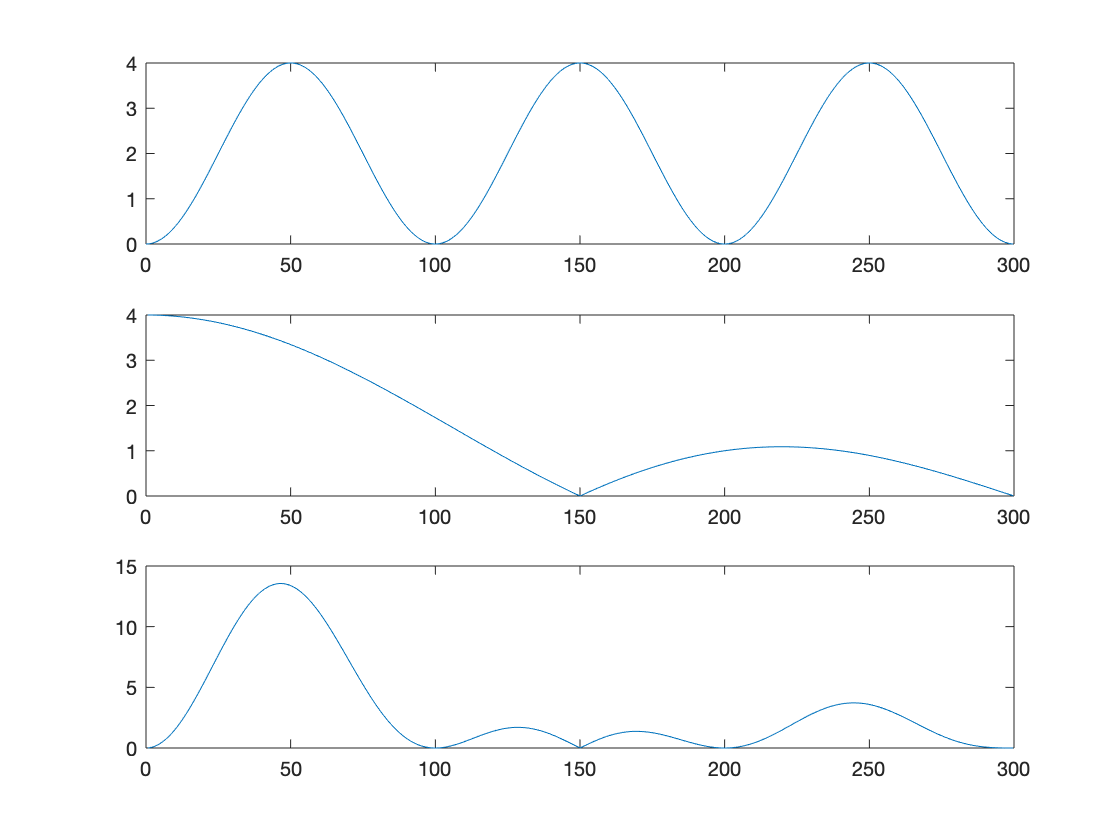

transferCharacteristic6 (600,6,2,4); figure;

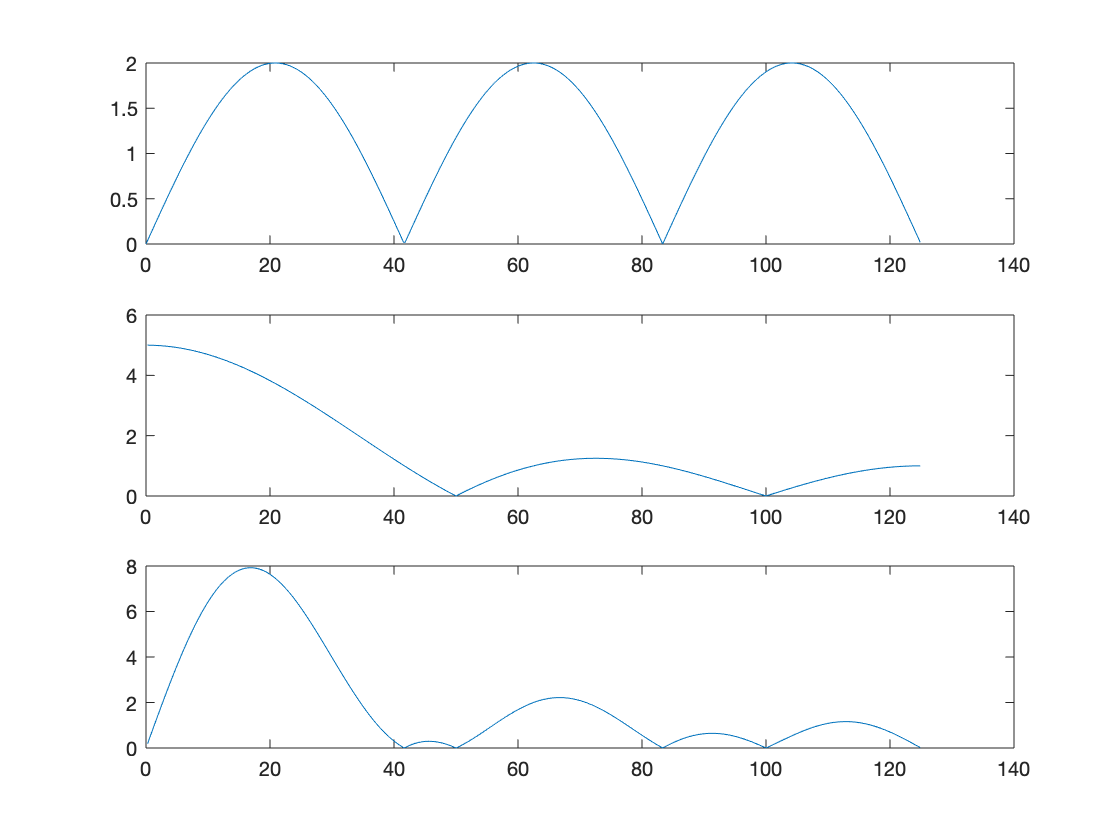

transferCharacteristic6 (250,6,1,5); figure;

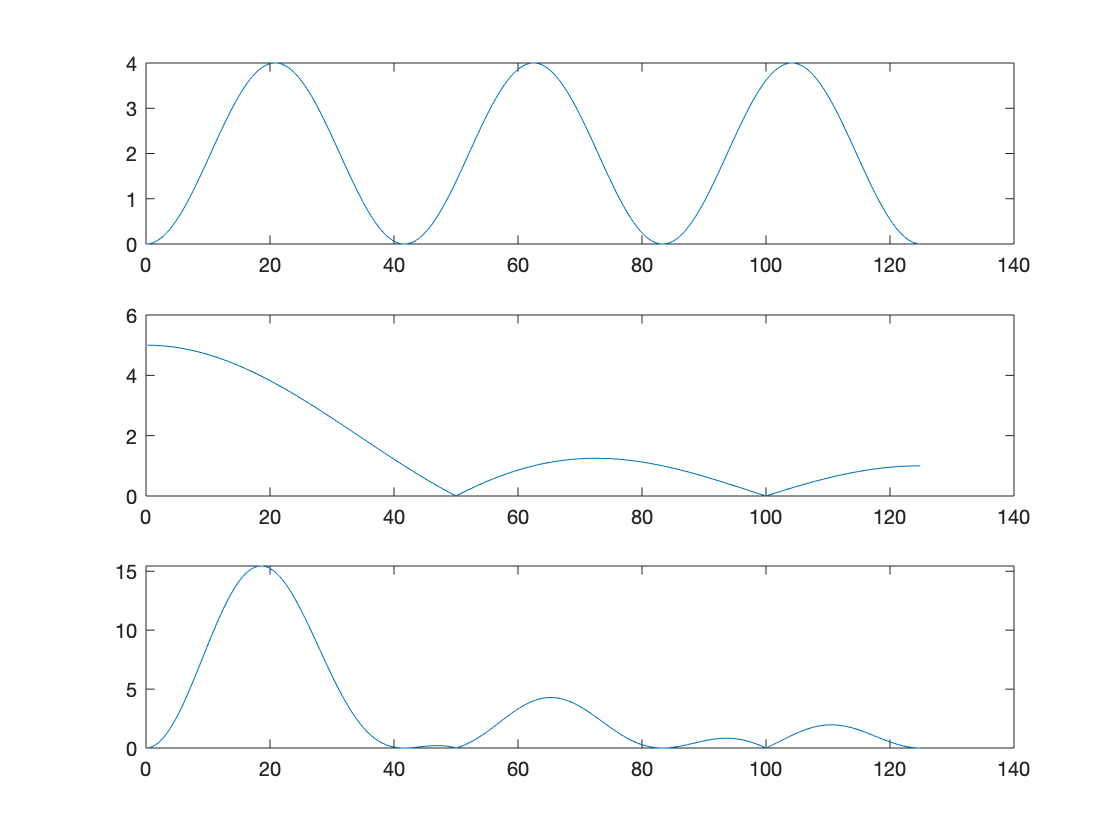

transferCharacteristic6 (250,6,2,5); figure;

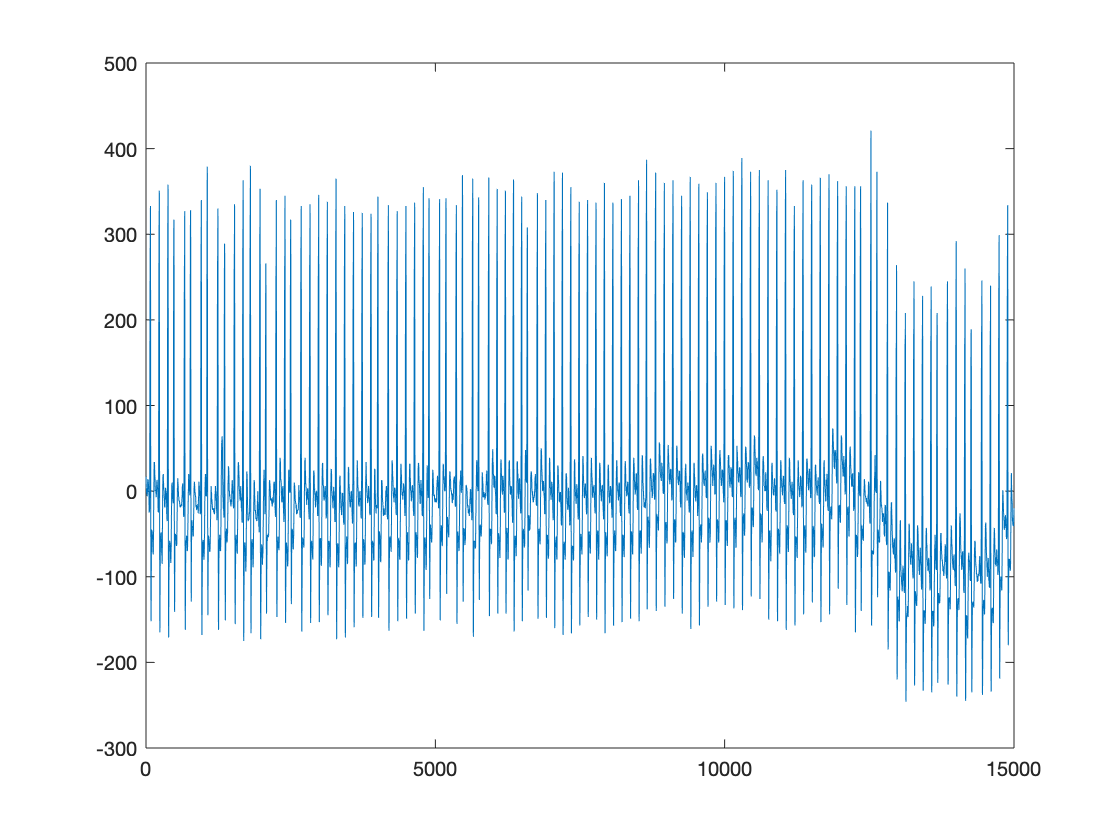

load ("s20501m.mat");
sig1 = val(1,:);
plot(sig1);

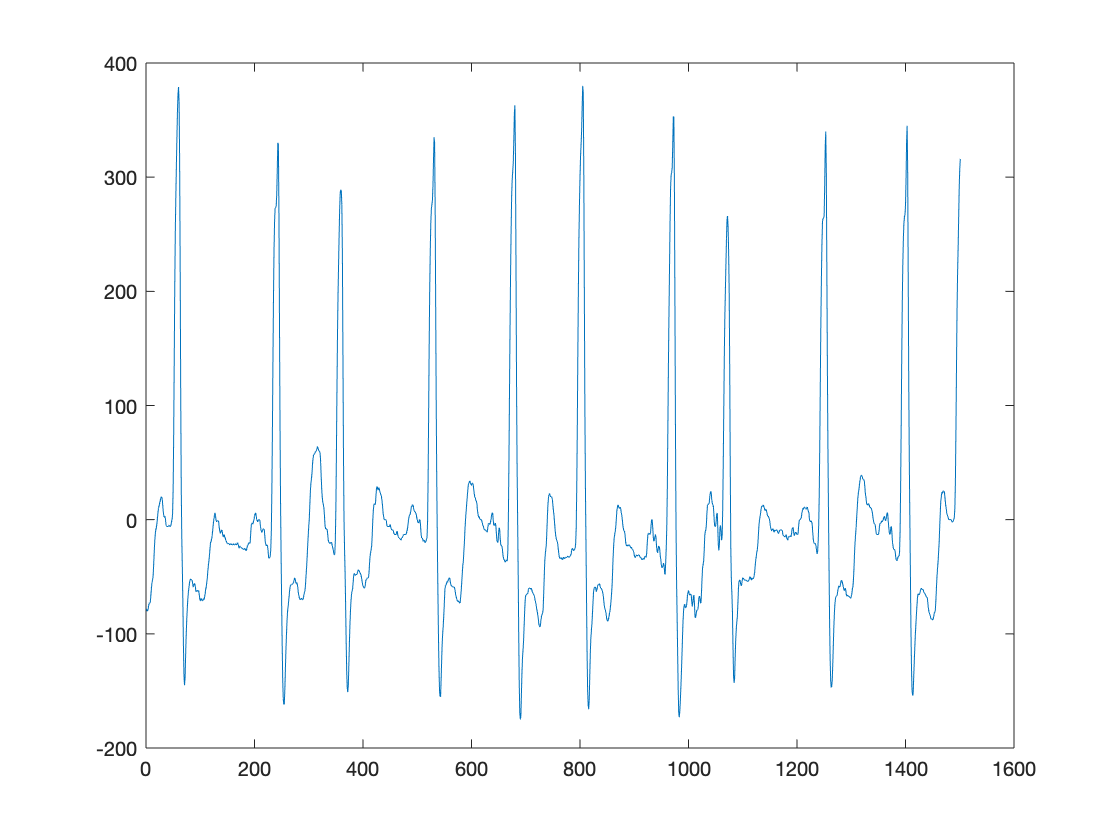

sig1 = val(1, 1000:2500);
plot(sig1);

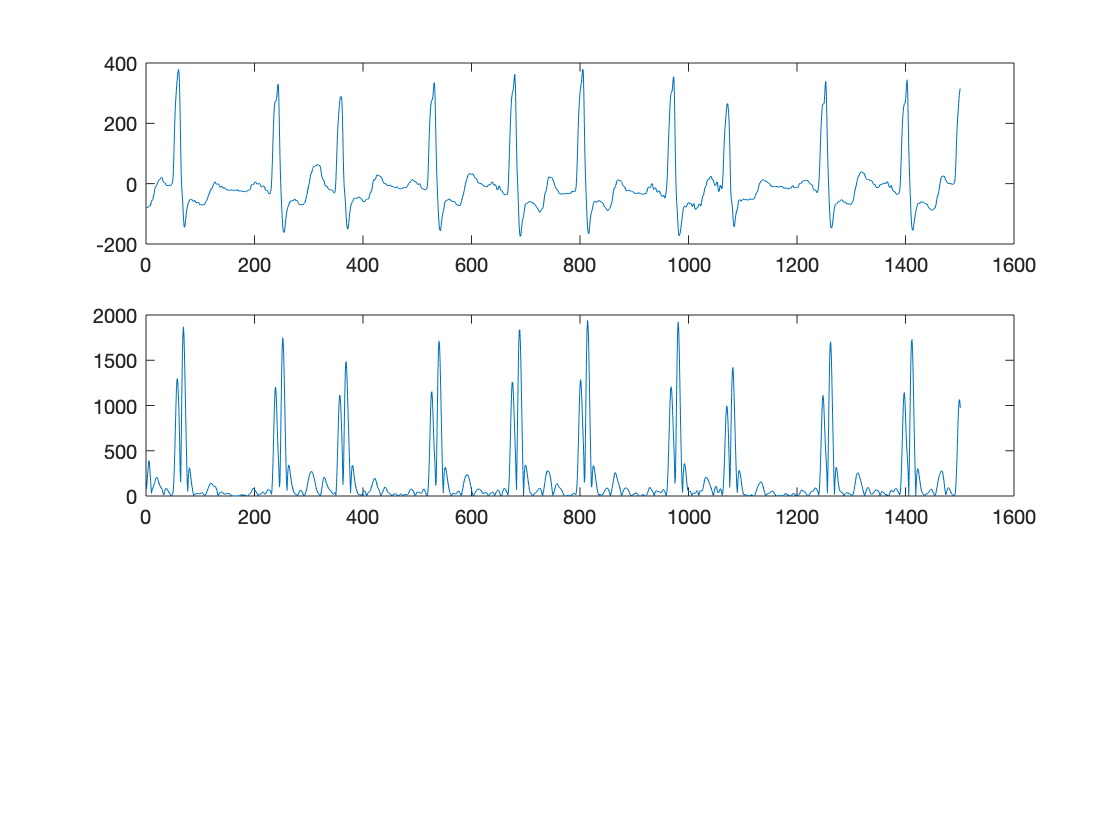

a1 = [1,-1];
b1 = conv([1,0,0,0,0,0,-1], [1,0,0,0,0,-1]);
fsig1 = abs(filter(b1,a1,sig1));  
subplot(3,1,1);plot(sig1);
subplot(3,1,2);plot(fsig1); figure;

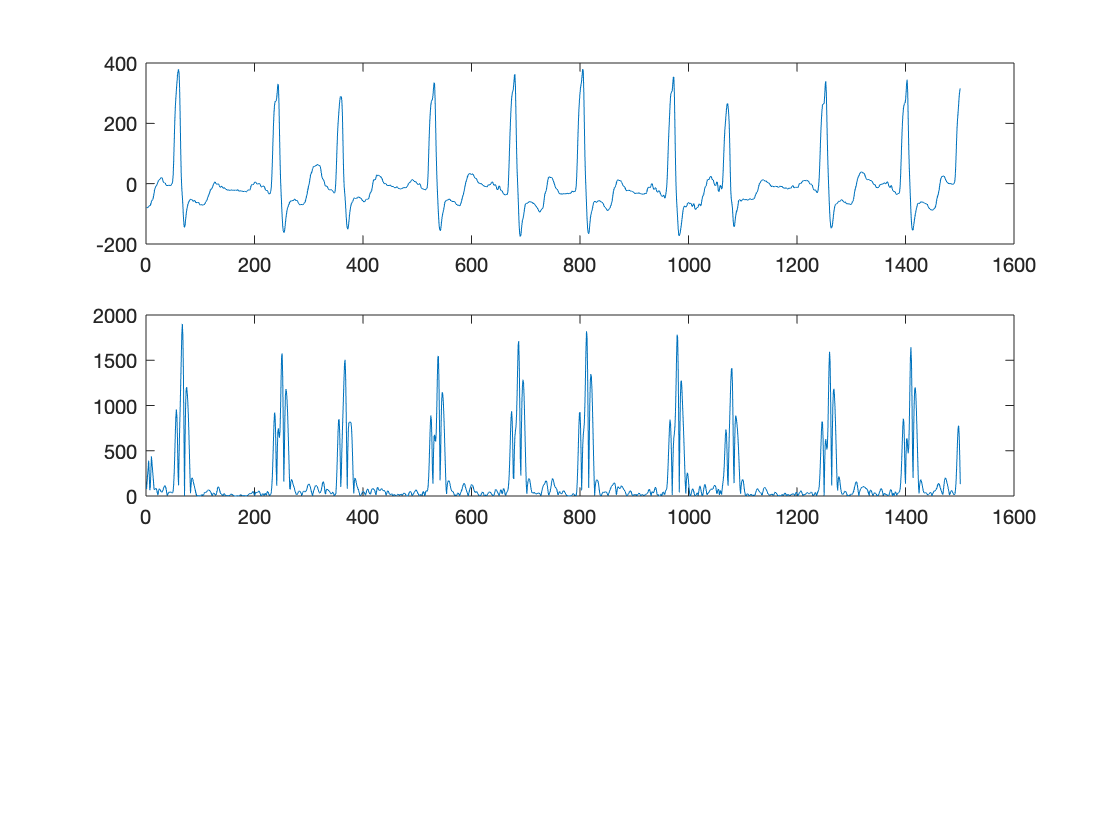

a2 = [1,-1];
b2 = conv(conv([1,0,0,0,0,-1],[1,0,0,0,0,-1]),[1,0,0,0,0,-1]);
fsig2 = abs(filter(b2,a2,sig1));
subplot(3,1,1);plot(sig1);
subplot(3,1,2);plot(fsig2); figure;

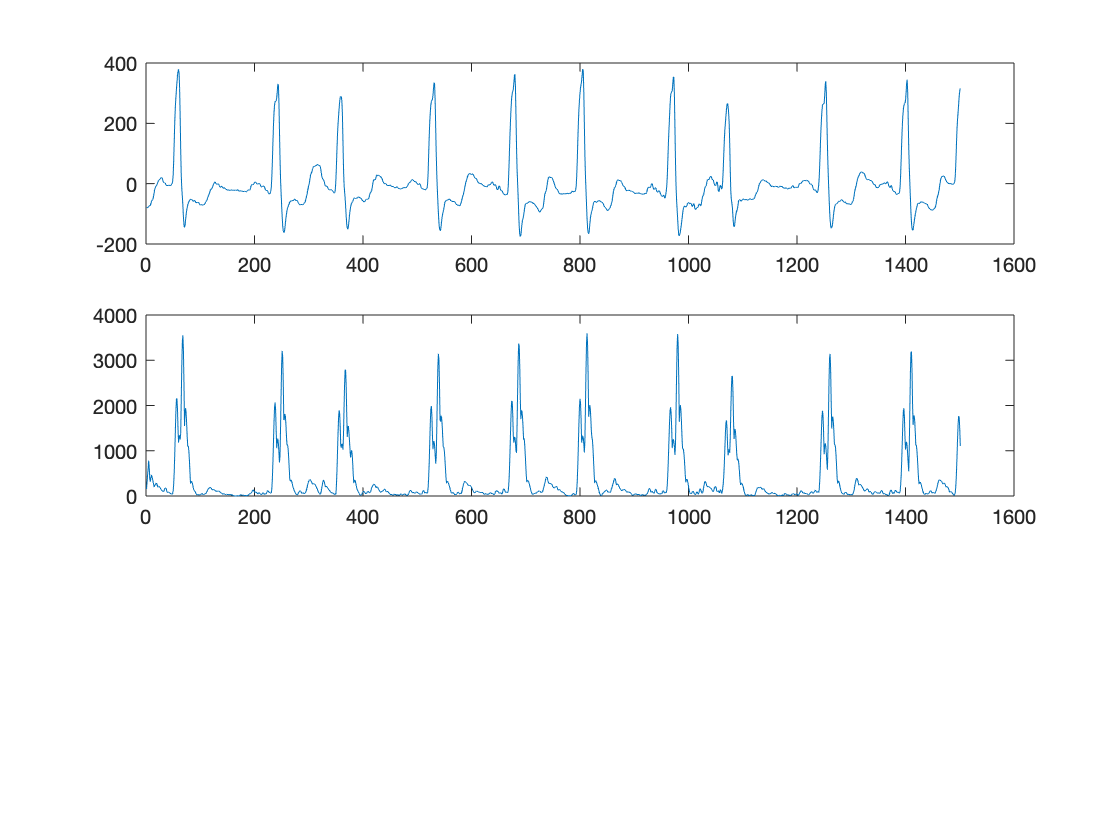

fsig3 = fsig1+fsig2;
subplot(3,1,1);plot(sig1);
subplot(3,1,2);plot(fsig3); figure;

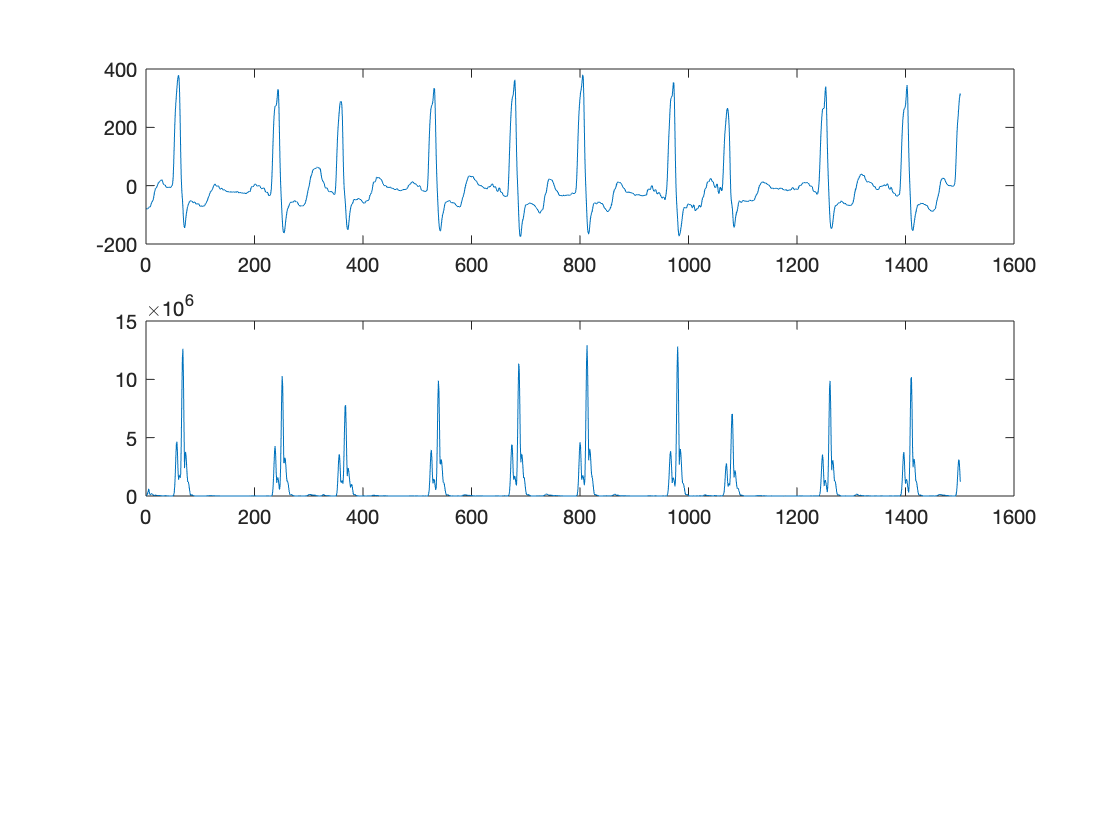

fsig3squared = fsig3.^2;
subplot(3,1,1);plot(sig1);
subplot(3,1,2);plot(fsig3squared); figure;